%% Inverse kinematics of KUKA KR 6 R 700 sixx
% Group B225 ROB-2 2021

close all;
clc;
clear all;

% Symbol definitions
syms theta1 theta2 theta3 theta4 theta5 theta6
vars = [theta1 theta2 theta3 theta4 theta5 theta6];

% Threshold for eliminating "almost" zeros
threshold = 5e-17;

% c controls if which tool is in use (TCP1 = 1, TCP2 = 2)
c = 1;

% t controls which test to run
t = 9;

% Testing frames
t1 =  [892.918509,   -58.901221,   195.314272,  -135.607924,    47.918253,  -137.553283 ];
t2 =  [861.418399,   -81.466506,   122.607075,  -134.577759,    34.278521,  -139.714720 ];
t3 =  [821.650939,  -104.480980,    55.863252,  -132.725251,    21.025482,  -142.743959 ];
t4 =  [774.826444,  -127.375889,    -3.823922,  -129.827193,     8.337691,  -146.870845 ];
t5 =  [722.342407,  -149.640053,   -55.637427,  -125.566674,    -3.527362,  -152.421231 ];
t6 =  [109.059872,  -198.792752,   933.581240,  -152.220513,    39.072302,   -96.350545 ];
t7 =  [-161.936576,  -572.635680,   741.951076,   137.474866,   -20.268640,  -106.779565];
t8 =  [-19.754117,   659.568277,   468.758125,   -38.629281,    -5.148395,   -83.289135 ];
t9 =  [268.556514,  -268.361952,   529.729516,   139.275879,    77.101404,   116.989383 ];
t10 = [63.355983,  -211.882726,  -347.792498,  -127.833711,   -30.214682,   148.441073  ];

% Testing statement
if (t == 1)
TBTarget_tcp1 = t1;
elseif (t == 2)
TBTarget_tcp1 = t2;
elseif (t == 3)
TBTarget_tcp1 = t3;
elseif (t == 4)
TBTarget_tcp1 = t4;
elseif (t == 5)
TBTarget_tcp1 = t5;
elseif (t == 6)
TBTarget_tcp1 = t6;
elseif (t == 7)
TBTarget_tcp1 = t7;
elseif (t == 8)
TBTarget_tcp1 = t8;
elseif (t == 9)
TBTarget_tcp1 = t9;
elseif (t == 10)
TBTarget_tcp1 = t10;
end

%% Target definition
% From RoboDK "Copy values" and paste in TBTarget_m
%TBTarget_tcp1 = [   552.000582,   469.084642,   708.574633,    84.359041,    72.236451,    -2.133738 ];
%TBTarget_tcp2 = [   548.288828,   418.381076,   753.721546,    86.599494,   -17.750823,    -0.683381 ];

% Evaluation of tool 
if (c == 1)
    TBTtarget = eulerZYX2T(TBTarget_tcp1(1,1), TBTarget_tcp1(1,2), TBTarget_tcp1(1,3), deg2rad(TBTarget_tcp1(1,4)), deg2rad(TBTarget_tcp1(1,5)), deg2rad(TBTarget_tcp1(1,6)));
else
    TBTtarget = eulerZYX2T(TBTarget_tcp2(1,1), TBTarget_tcp2(1,2), TBTarget_tcp2(1,3), deg2rad(TBTarget_tcp2(1,4)), deg2rad(TBTarget_tcp2(1,5)), deg2rad(TBTarget_tcp2(1,6)));
end




%% Base and wrist translations
TB_0 = [1   0    0      0;
        0   -1    0     0;
        0    0   -1   400;
        0    0    0    1];
 
 
T6_W = [-1   0     0     0;
        0    1     0     0;
        0    0    -1   -80;
        0    0     0    1];

%% Tool Translations

% Calulation of translation of wrist to cover gripper 
TWT_TCP1 = eulerZYX2T(0,0,144.650, 0, 0 ,0);

% Calculation of translation of wrist to PCB gripper
TWT_TCP2 = eulerZYX2T(-58.500,0,110, 0, -pi/2, 0);

%% Target from tools

%  The end product should be the following matrices
%  When taking the product of the theta calculations
T06target_TCP1 = inv(TB_0)*TBTtarget*inv(TWT_TCP1)*inv(T6_W);

T06target_TCP2 = inv(TB_0)*TBTtarget*inv(TWT_TCP2)*inv(T6_W);


% Evaluation of tool 
if (c == 1)
    T06target = T06target_TCP1;
else
    T06target = T06target_TCP2;
end

%% Computation of theta values
%  Geometric solving atan2(y,x)

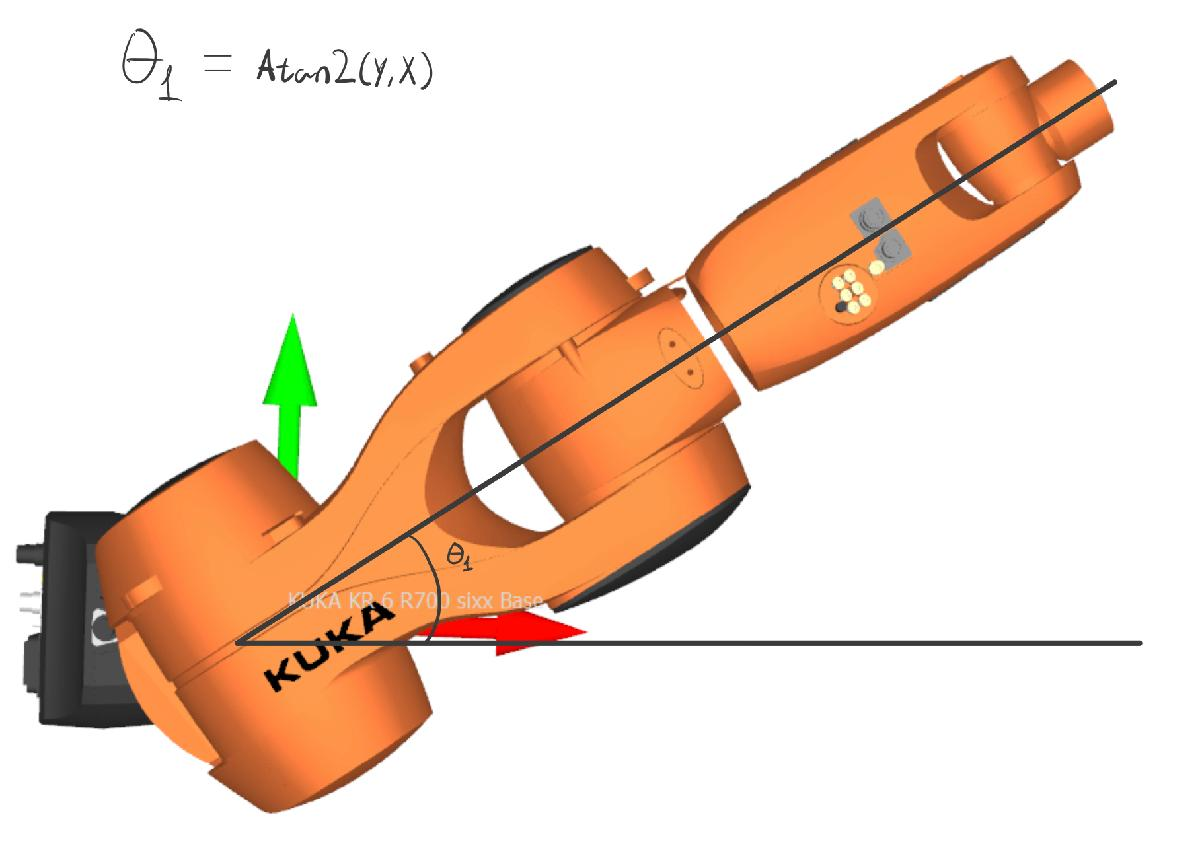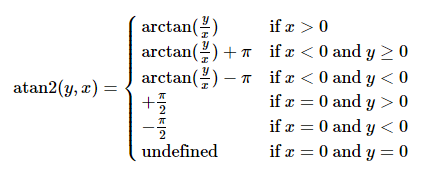

% Calculation of theta1
theta1 = atan2(T06target(2,4),T06target(1,4));

% Round to zero, if infinite close to zero

if (theta1<threshold)
    theta1_deg = radtodeg(round(theta1));
else
    theta1_deg = radtodeg(theta1);
end

theta1_deg

theta1_deg = 80.0000

% Definition of target
T0_1=TDH(0,0,0,theta1);

T16target = inv(T0_1)*T06target;

% Computation of L1

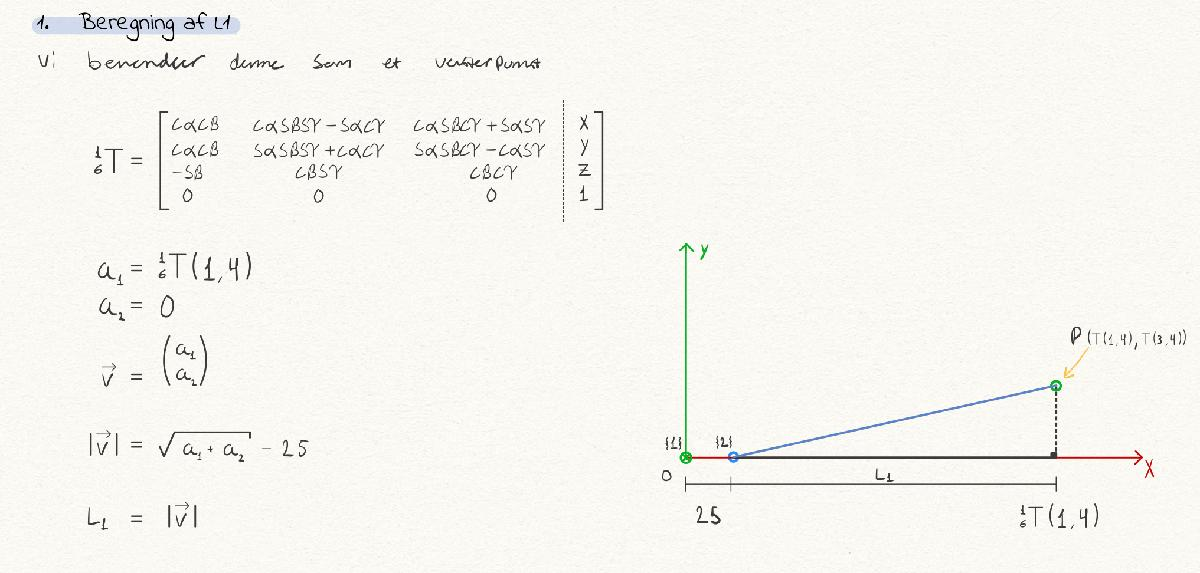

% This line is treated as a vector 
% for the purpose of calculating the length

a_1 = T16target(1,4);
a_2 = 0;

v = [a_1; a_2];

% The euclidic norm is the length of the vector in ordinary vector spaces
% like R^2 and R^3

L1 = norm(v)-25;

% Computation of L2

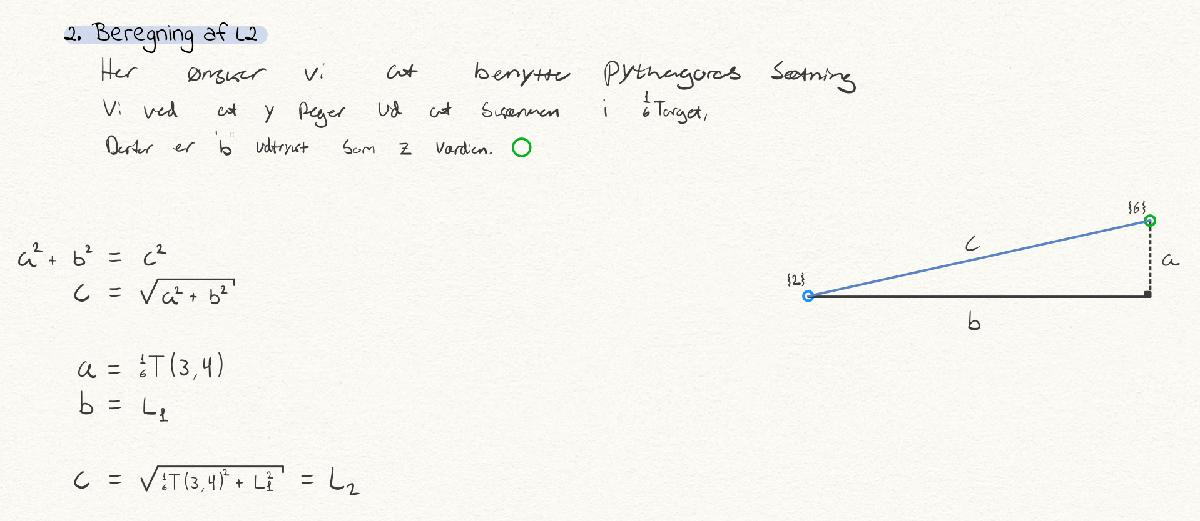

% We use pythagoras theorem to compute the length of L2

L2 = sqrt((T16target(3,4)^2)+(L1^2));

% Computation of L3

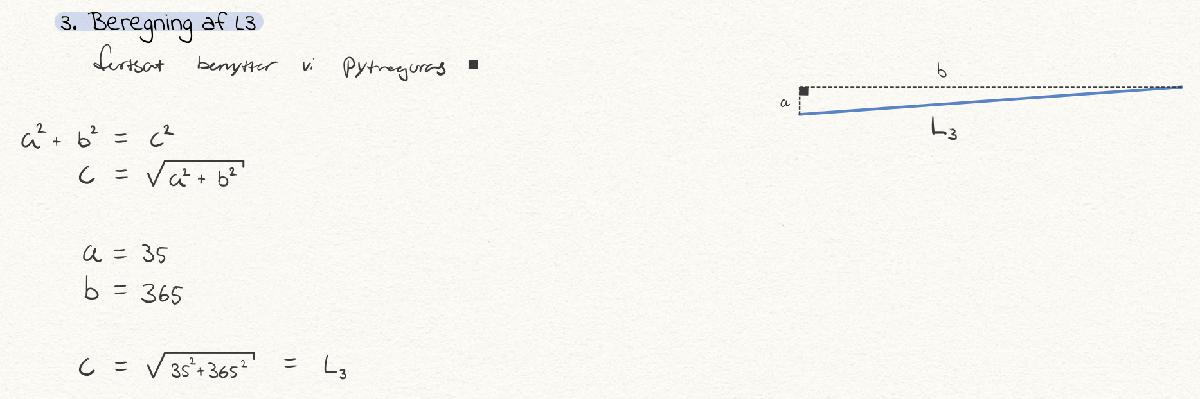

% We use pythagoras theorem to compute the length of L3

L3 = sqrt(35^2+365^2);

% Computation of theta_2_1

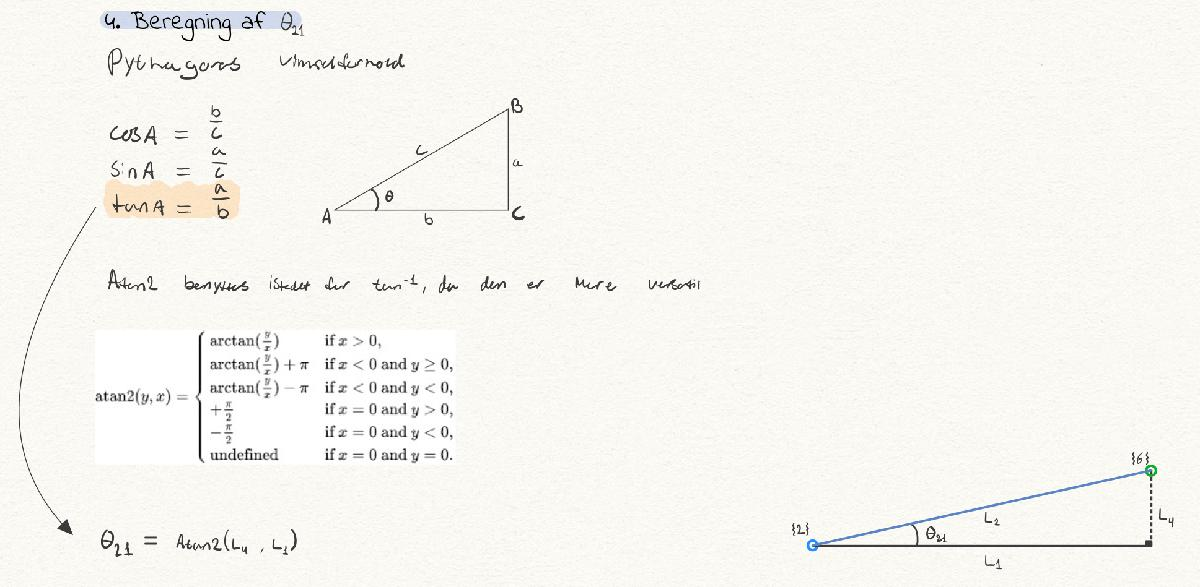

% We use pythagoras theorem that describes angles with given sides

% Definition of L4
L4 = T16target(3,4);

theta2_1 = atan2(L4, L1);

% Computation of theta2_2

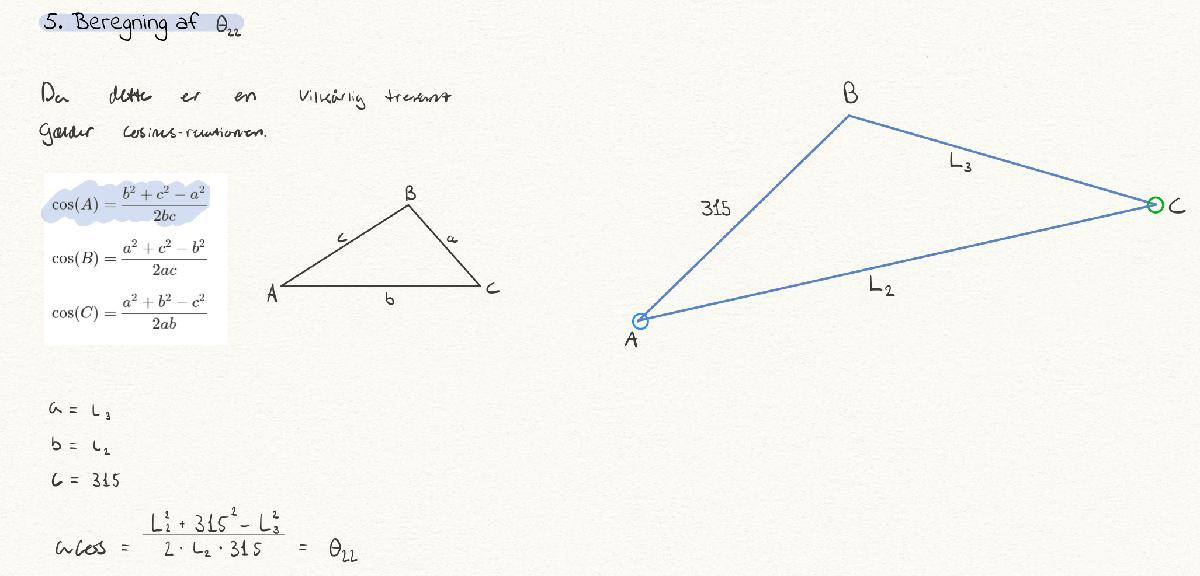

% We use the cosine relation since this is a arbitrary triangle

theta2_2 = acos(((L2^2)+(315^2)-(L3^2))/(2*L2*315));


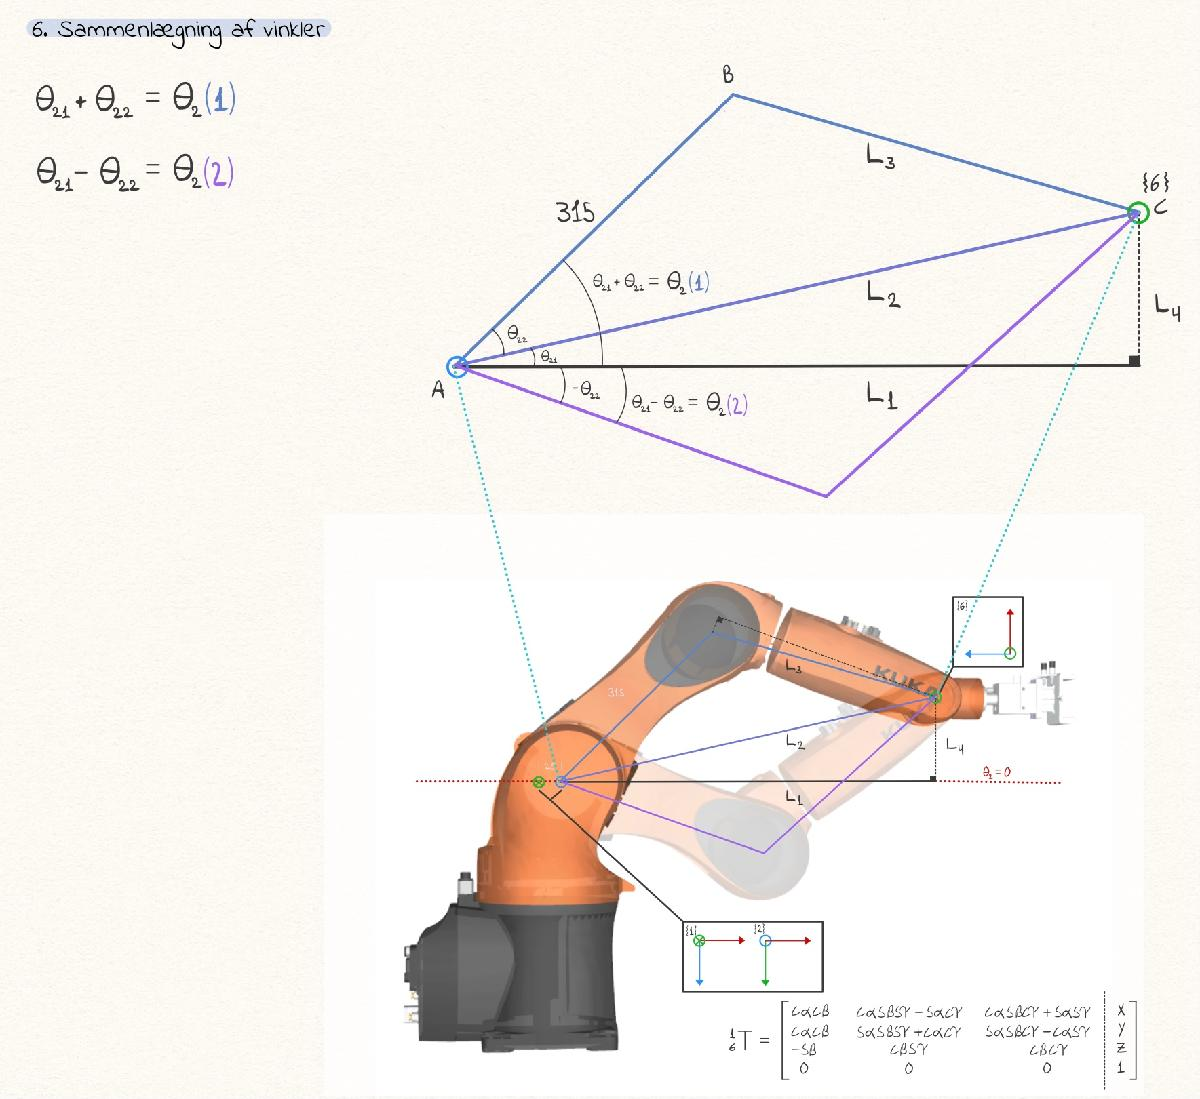

% Aggregation of angle values

% Solution 1
theta2_s1 = theta2_1+theta2_2;

% Solution 2
theta2_s2 = theta2_1-theta2_2;

% radians to degrees (1)
rad2deg(theta2_s1)

ans = 39.8729

% radians to degrees (2)
rad2deg(theta2_s2)

ans = -88.7296

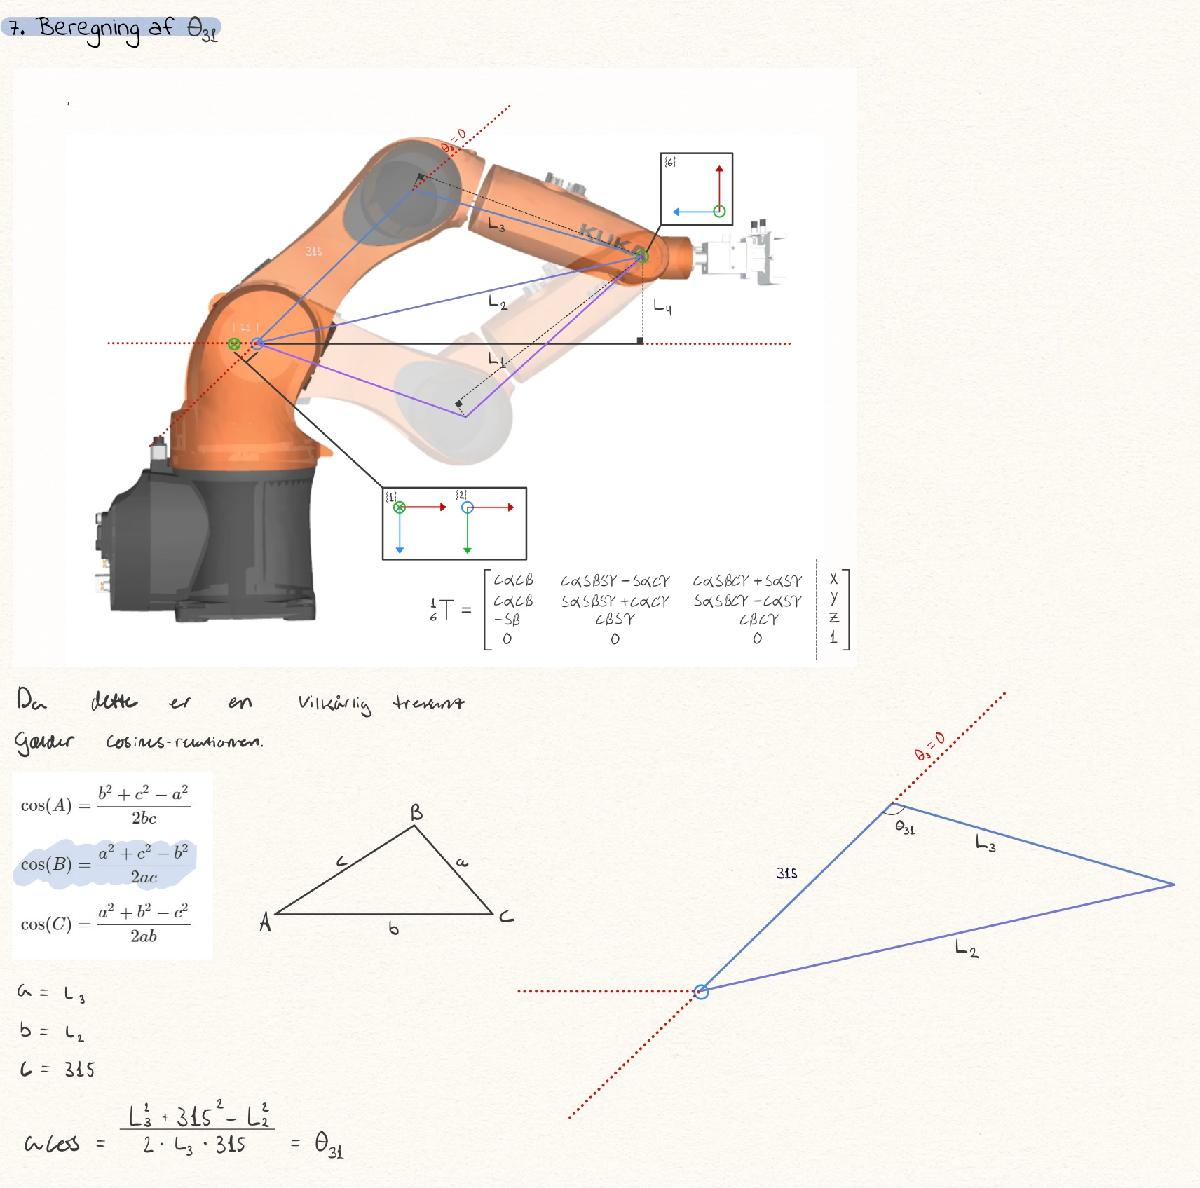

% Calculation of theta3_1
theta3_1 = acos(((L3^2)+(315^2)-(L2^2))/(2*L3*315));

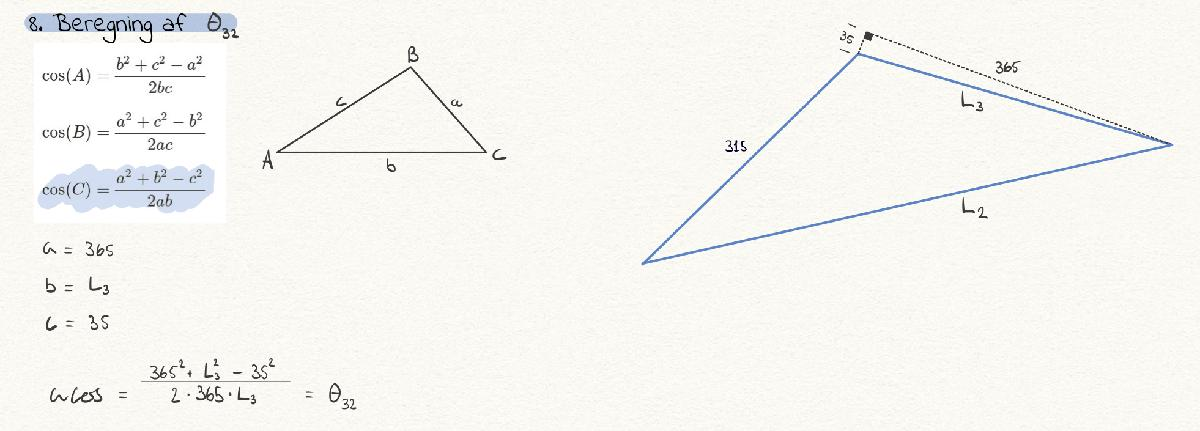

% Calculation of theta3_2
theta3_2 = acos(((365^2)+(L3^2)-(35^2))/(2*365*L3));

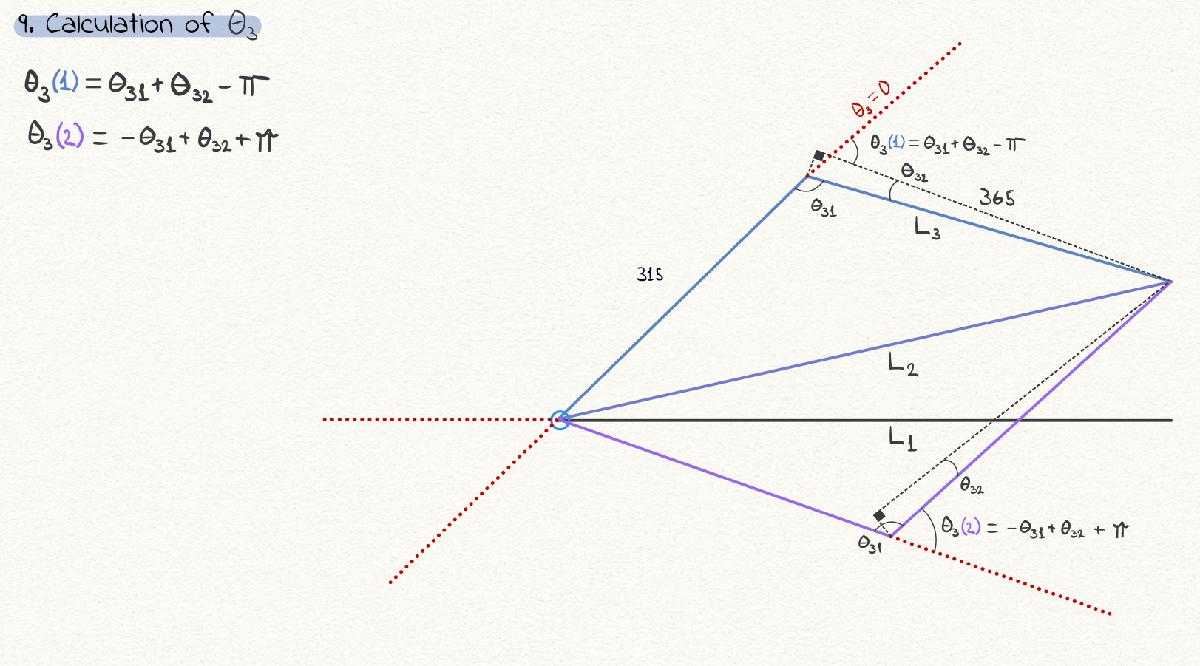

% Aggregation of angle values
% Solution 1
theta3_s1 = theta3_1+theta3_2-pi;

% Solution 2
% Fixed while evaluating the geometric solution, do check in validation
theta3_s2 = -theta3_1+theta3_2+pi;

% Geometrically this is correct
%theta3_s2 = pi-theta3_1;

% radians to degrees (1)
rad2deg(theta3_s1)

ans = -109.5473


% radians to degrees (2)
rad2deg(theta3_s2)

ans = 120.5021

% Calculation of theta 5, 6 and 7
% Setup of DH Parameters for angle determination

DH = [pi/2   ,35     ,-365    ,theta4 ;
     -pi/2   ,0      ,0       ,theta5 ;
      pi/2   ,0      ,0       ,theta6];   

% We save the no. of columns int or DH matrix (For iteration)
N=size(DH,1);

% Generic multiplication variable
B=1;

% This for loop iterates the general matrix form on the last three entries
% Of the DH parameters using the general form from CRAIG pg. 75 ch. 3.5 eq. (3.6)
for i=1:N   
A{i} = [cos(DH(i,4))                ,-sin(DH(i,4))              ,0              ,DH(i,2)              ;
        sin(DH(i,4))*cos(DH(i,1))   ,cos(DH(i,4))*cos(DH(i,1))  ,-sin(DH(i,1))  ,-sin(DH(i,1))*DH(i,3);
        sin(DH(i,4))*sin(DH(i,1))   ,cos(DH(i,4))*sin(DH(i,1))  ,cos(DH(i,1))   ,cos(DH(i,1))*DH(i,3) ;
        0                           ,0                          ,0              ,1                   ];
B=(B*A{i});
end

% Generation of transformation matrices
T3_4    =A{1};
T4_5    =A{2};
T5_6    =A{3};

% The following symbolic visualization of T3_6 shows that we can solve
% Theta5 by using the entry that states -cos(theta5) -> T3_6(2, 3)
T3_6 = T3_4*T4_5*T5_6

$$T3\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & 35\\ \cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{5}\right) & 365\\ \cos\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)+\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right)\,\cos\left(\theta_{6}\right)-\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & \sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Indivudal transformation matrices
T0_1    = TDH(0    , 0  , 0   ,theta1);        
T1_2_s1 = TDH(pi/2 , 25 , 0   ,theta2_s1);     
T1_2_s2 = TDH(pi/2 , 25 , 0   ,theta2_s2);     
T2_3_s1 = TDH( 0   , 315, 0   ,theta3_s1-pi/2);
T2_3_s2 = TDH( 0   , 315, 0   ,theta3_s2-pi/2);
T3_4    = TDH(pi/2 , 35 , -365,theta4);        
T4_5    = TDH(-pi/2, 0  , 0   ,theta5);        
T5_6    = TDH(pi/2 , 0  , 0   ,theta6);        

% Computation of T0_3
T0_3_1      = T0_1*T1_2_s1*T2_3_s1;
T0_3_2      = T0_1*T1_2_s2*T2_3_s2;

% Computation of T3_6
T36target_1 = inv(T0_3_1)*T06target;
T36target_2 = -inv(T0_3_2)*T06target;

% Computation of T3_6 value-based
T3_6      = T3_4*T4_5*T5_6;

% Computation of theta5 from our knowledge about entry (2, 3)
theta5_s1 =   -acos(-T36target_1(2,3));
theta5_s2 =   -acos(T36target_2(2,3)) ;

% Looking at T3_6 we know that theta4 can be derived from T36target(3,3) and T36target(1,3)
theta4_s1 = -atan2(T36target_1(3,3)*sin(theta5_s1),-T36target_1(1,3)*sin(theta5_s1));
%theta4_s2 = -atan2(-T36target_1(3,3)*sin(-theta5_s1),-T36target_1(1,3)*sin(-theta5_s1));
theta4_s2 = atan2(T36target_2(3,3)*sin(theta5_s2),T36target_2(1,3)*sin(theta5_s2));

% Likewise we T3_6 shows that we can derive theta6 from T36target(2,2) and
% T36target(2,1)
theta6_s1 = -atan2(T36target_1(2,2)*sin(-theta5_s1),T36target_1(2,1)*sin(-theta5_s1));
theta6_s2 = -atan2(T36target_2(2,2)*sin(theta5_s2),T36target_2(2,1)*sin(theta5_s2));

## Solutions to IKT

% Solution 1
Theta1_deg    =  rad2deg(theta1)

Theta1_deg = 80.0000

theta2_s1_deg =  rad2deg(theta2_s1)

theta2_s1_deg = 39.8729

theta3_s1_deg =  rad2deg(theta3_s1)

theta3_s1_deg = -109.5473

theta4_s1_deg =  rad2deg(theta4_s1)

theta4_s1_deg = -100.0953

theta5_s1_deg = -rad2deg(theta5_s1)

theta5_s1_deg = 99.9038

theta6_s1_deg =  rad2deg(theta6_s1)

theta6_s1_deg = 8.5716

% Solution 2 
Theta1_deg    =  rad2deg(theta1)

Theta1_deg = 80.0000

theta2_s2_deg =  rad2deg(theta2_s2)

theta2_s2_deg = -88.7296

theta3_s2_deg =  rad2deg(theta3_s2)

theta3_s2_deg = 120.5021

theta4_s2_deg =  rad2deg(theta4_s2)

theta4_s2_deg = -78.1870

theta5_s2_deg = -rad2deg(theta5_s2)

theta5_s2_deg = 97.7647

theta6_s2_deg =  rad2deg(theta6_s2)

theta6_s2_deg = 111.6999